% Feedforward + Feedback Control for Staubli TX90 with Simulink ODE45 solver
clear all; clc;

% Define manipulator parameters
n = 6; % Number of joints
g = [0; 0; -9810]; % Gravity vector (mm/s^2)

% R{i} Orientation of frame i-1 in i
R{1} = eye(3);
R{2} = [[1,0,0];[0,0,1];[0,1,0]];
R{3} = eye(3);
R{4} = [[-1,0,0];[0,0,-1];[0,-1,0]];
R{5} = [[0,1,0];[0,0,1];[1,0,0]];
R{6} = [[0,0,1];[0,-1,0];[1,0,0]];

% p{i} position of frame i-1 in i (in mm)
p{1} = [-19.14;-24.76;-410.64];
p{2} = [-30.85;271.45;-195.43];
p{3} = [-0.01;296.72;155.18];
p{4} = [2;-15;-355.72];
p{5} = [212.52;-1.97;-0.14];
p{6} = [0.17;0;-70.38];

% Configuration matrices M_{i,i-1} (frames at centers of mass)
M{1} = [R{1},p{1};0 0 0 1]; % M_{1,0}
M{2} = [R{2},p{2};0 0 0 1]; % M_{2,1}
M{3} = [R{3},p{3};0 0 0 1]; % M_{3,2}
M{4} = [R{4},p{4};0 0 0 1]; % M_{4,3}
M{5} = [R{5},p{5};0 0 0 1]; % M_{5,4}
M{6} = [R{6},p{6};0 0 0 1]; % M_{6,5}
M{7} = [eye(3),[0;0;1];0 0 0 1]; % M_{7,6}

% Screw axes A_i (expressed in COM frames) (in mm)
A{1} = [[0; 0; 1]; [-24.76; 19.21; 0]]; % Joint 1
A{2} = [[0; 0; 1]; [206.86; 0.20; 0]]; % Joint 2
A{3} = [[0; 0; 1]; [3.57; 0.08; 0]]; % Joint 3
A{4} = [[0; 0; 1]; [0.01; 1.7; 0]]; % Joint 4
A{5} = [[0; 0; 1]; [0; 22.96; 0]]; % Joint 5
A{6} = [[0; 0; 1];[0; -0.24; 0]]; % Joint 6

% Mass array (grams)
masses = {16934.57, 14350.90, 7501.51, 6420.43, 568.77, 30.98};

% Inertia tensor cell array (grams * mm^2)
inertias = {
    [222318392.93, 16499490.67, 23794307.09; ...
     16499490.67, 208958862.85, 31663043.13; ...
     23794307.09, 31663043.13, 157080928.32], ...
    [595207225.54, 7542.68, 4677.18; ...
     7542.68, 59862591.19, 3766250.53; ...
     4677.18, 3766250.53, 625682621.55], ...
    [58901544.85, -792.98, 60.73; ...
     -792.98, 34271484.89, 3671694.41; ...
     60.73, 3671694.41, 56883800.79], ...
    [103998943.85, 3156.05, -1379337.12; ...
     3156.05, 98782248.66, -7047.88; ...
     -1379337.12, -7047.88, 19071254.39], ...
    [382719.09, -11.58, 899.66; ...
     -11.58, 1083683.83, 1.21; ...
     899.66, 1.21, 1122865.92], ...
    [382719.09, -11.58, 899.66; ...
     -11.58, 1083683.83, 1.21; ...
     899.66, 1.21, 1122865.92]
};

G = compute_spatial_inertia(masses, inertias);

% Simulation parameters
tf = 1; % Simulation time per segment (s)
N = 500; % Number of time points for output per segment

% Initial joint angles
theta_start = (pi/180)*[10; 10; 10; 10; 10; 10];

% Waypoint cell array (4x4 transformation matrices)
waypoints = {
    [-0.968409, -0.000000, 0.249366, 696.292570; ...
     -0.000000, 1.000000, 0.000000, 50.000000; ...
     -0.249366, 0.000000, -0.968409, -504.783037; ...
     0.000000, 0.000000, 0.000000, 1.000000], ...
    [-0.547677, -0.824719, 0.141027, 352.547378; ...
     -0.798665, 0.565543, 0.205657, 602.522771; ...
     -0.249366, 0.000000, -0.968409, -504.783037; ...
     0.000000, 0.000000, 0.000000, 1.000000]
};


% Compute trajectories for each waypoint
num_waypoints = length(waypoints);
trajectories = cell(num_waypoints, 1); % Cell array to store trajectories
theta_current = theta_start; % Start with initial configuration
% External wrench
    F_tip = {[0; 0; 0; 0; 0; 0],...
        [0; 0; 0; 0; 0; 400*-9810]}; % (N·m 1e-9, N 1e-6)
for w = 1:num_waypoints
    % Desired end-effector pose
    T_d = waypoints{w};
    
    % Compute inverse kinematics solutions and select best configuration
    theta_set_deg = inverse_kinematics_all_configs(T_d);
    if isempty(theta_set_deg)
        error('No valid inverse kinematics solution found for waypoint %d', w);
    end
    % Choose configuration with minimum total joint displacement
    [~, idx] = min(sum(abs(theta_set_deg - rad2deg(theta_current')), 2));
    theta_end = deg2rad(theta_set_deg(idx, :))'; % Convert to radians
    
    % Display selected configuration
    fprintf('Waypoint %d Configuration (in degrees):\n', w);
    fprintf('θ1: %.2f, θ2: %.2f, θ3: %.2f, θ4: %.2f, θ5: %.2f, θ6: %.2f\n', ...
        theta_set_deg(idx, :));
    
    % Generate desired trajectory
    tspan = linspace(0, tf, N+1);
    [theta_d, theta_dot_d, theta_ddot_d] = jointspace_traj(theta_current, theta_end, tf, N, 'quintic');
    
    % Interpolate desired trajectories for ODE solver
    theta_d_fun = @(t) interp1(tspan, theta_d', t)';
    theta_dot_d_fun = @(t) interp1(tspan, theta_dot_d', t)';
    theta_ddot_d_fun = @(t) interp1(tspan, theta_ddot_d', t)';
    
    % PD control gains
    kp = 10000000000 * eye(n); % Proportional gain
    kd = 2000000000 * eye(n); % Derivative gain
    
    % Initial conditions
    y0 = [theta_current; zeros(n,1)]; % [theta; theta_dot]
    
    
    
    % ODE solver options
    options = odeset('RelTol', 1e-4, 'AbsTol', 1e-6);
    
    % Solve using ode45
    [t, y] = ode45(@(t, y) odefun(t, y, theta_d_fun, theta_dot_d_fun, theta_ddot_d_fun, ...
        F_tip{w}, M, A, G, g, kp, kd, n), tspan, y0, options);
    
    % Extract results
    theta = y(:, 1:n)';
    theta_dot = y(:, n+1:2*n)';
    tau_array = zeros(n, N+1);
    
    % Compute torques
    for k = 1:N+1
        tau_ff = inverse_dynamics(theta_d(:,k), theta_dot_d(:,k), theta_ddot_d(:,k), F_tip{w}, M, A, G, g);
        e = theta_d(:,k) - theta(:,k);
        e_dot = theta_dot_d(:,k) - theta_dot(:,k);
        tau_array(:,k) = tau_ff + kp * e + kd * e_dot;
    end
    
    % Store trajectory
    trajectories{w} = struct('time', t, 'theta_d', theta_d, 'theta_dot_d', theta_dot_d, ...
        'theta_ddot_d', theta_ddot_d, 'theta', theta, 'theta_dot', theta_dot, 'tau', tau_array);
    
    % Update theta_current for next trajectory
    theta_current = theta(:,end);
end

Waypoint 1 Configuration (in degrees):


θ1: 0.00, θ2: 75.56, θ3: 90.00, θ4: 0.00, θ5: -0.00, θ6: 0.00


Waypoint 2 Configuration (in degrees):


θ1: 55.56, θ2: 75.56, θ3: 90.00, θ4: -67.69, θ5: -0.00, θ6: 67.69


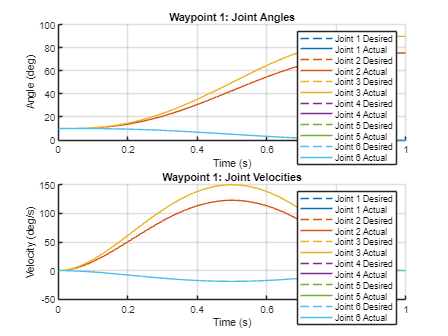

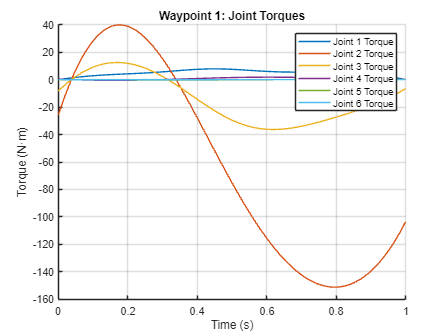

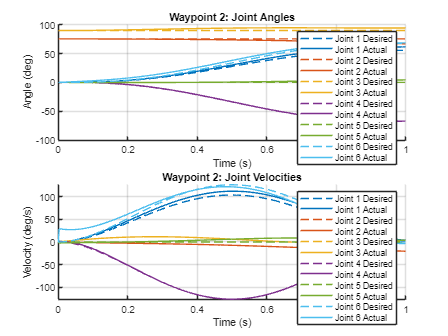

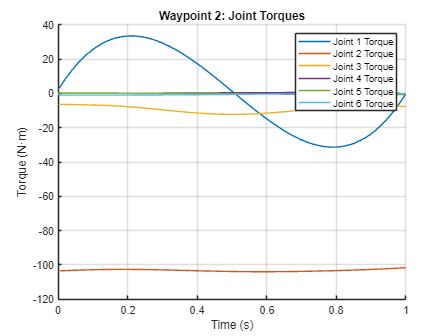


% Plot all trajectories
for w = 1:num_waypoints
    t = trajectories{w}.time;
    theta_d = trajectories{w}.theta_d;
    theta = trajectories{w}.theta;
    theta_dot_d = trajectories{w}.theta_dot_d;
    theta_dot = trajectories{w}.theta_dot;
    tau_array = trajectories{w}.tau;
    
    % Plot joint angles and velocities
    figure('Name', sprintf('Trajectory %d', w));
    
    % Joint angles
    subplot(2,1,1);
    hold on;
    colors = lines(n);
    for i = 1:n
        plot(t, rad2deg(theta_d(i,:)), 'Color', colors(i,:), 'LineStyle', '--', ...
            'DisplayName', sprintf('Joint %d Desired', i));
        plot(t, rad2deg(theta(i,:)), 'Color', colors(i,:), 'LineStyle', '-', ...
            'DisplayName', sprintf('Joint %d Actual', i));
    end
    title(sprintf('Waypoint %d: Joint Angles', w));
    xlabel('Time (s)');
    ylabel('Angle (deg)');
    legend('show');
    grid on;
    hold off;
    
    % Joint velocities
    subplot(2,1,2);
    hold on;
    for i = 1:n
        plot(t, rad2deg(theta_dot_d(i,:)), 'Color', colors(i,:), 'LineStyle', '--', ...
            'DisplayName', sprintf('Joint %d Desired', i));
        plot(t, rad2deg(theta_dot(i,:)), 'Color', colors(i,:), 'LineStyle', '-', ...
            'DisplayName', sprintf('Joint %d Actual', i));
    end
    title(sprintf('Waypoint %d: Joint Velocities', w));
    xlabel('Time (s)');
    ylabel('Velocity (deg/s)');
    legend('show');
    grid on;
    hold off;
    drawnow;
    % Plot joint torques
    figure('Name', sprintf('Torques for Trajectory %d', w));
    hold on;
    for i = 1:n
        plot(t, tau_array(i,:)/1e9, 'Color', colors(i,:), 'LineStyle', '-', ...
            'DisplayName', sprintf('Joint %d Torque', i));
    end
    title(sprintf('Waypoint %d: Joint Torques', w));
    xlabel('Time (s)');
    ylabel('Torque (N·m)');
    legend('show');
    grid on;
    hold off;
    drawnow;
end


% ODE function for ode45

function dydt = odefun(t, y, theta_d_fun, theta_dot_d_fun, theta_ddot_d_fun, F_tip, M, A, G, g, kp, kd, n)
    theta = y(1:n);
    theta_dot = y(n+1:2*n);
    
    % Compute feedforward and feedback torques
    tau_ff = inverse_dynamics(theta_d_fun(t), theta_dot_d_fun(t), theta_ddot_d_fun(t), F_tip, M, A, G, g);
    e = theta_d_fun(t) - theta;
    e_dot = theta_dot_d_fun(t) - theta_dot;
    tau = tau_ff + kp * e + kd * e_dot;
    
    % Compute acceleration
    theta_ddot = compute_forward_dynamics(theta, theta_dot, tau, F_tip, M, A, G, g);
    
    % State derivative
    dydt = [theta_dot; theta_ddot];
end

% Dynamics functions
function J = compute_jacobian(theta, M, A)
    n = length(theta);
    J_s = zeros(6, n); % Spatial Jacobian
    
    M_0_i = cell(n, 1);
    T = eye(4);
    for i = 1:n
        T = T  / M{i};
        M_0_i{i} = T;
    end
    
    S = cell(n, 1);
    for i = 1:n
        Ad_M_0_i = adjoint(inv(M_0_i{i}));
        S{i} = Ad_M_0_i * A{i};
    end
    
    T = eye(4);
    for i = 1:n
        Ad_T = adjoint(T);
        J_s(:,i) = Ad_T * S{i};
        T = T * expm(skew(S{i}) * theta(i));
    end
    J=J_s;
%     Ad_T_inv = adjoint(inv(T));
%     J = Ad_T_inv * J_s;
end

function tau = inverse_dynamics(theta, theta_dot, theta_ddot, F_tip, M, A, G, g)
    n = length(theta);
    nu = cell(n+1, 1);
    nu_dot = cell(n+1, 1);
    F = cell(n+1, 1);
    tau = zeros(n, 1);
    
    nu{1} = zeros(6,1);
    nu_dot{1} = [zeros(3,1); -g];
    F{n+1} = F_tip;
    
    for i = 1:n
        T_i_im1 = expm(skew(A{i}) * theta(i)) * M{i};
        Ad_T_i_im1 = adjoint(T_i_im1);
        nu{i+1} = A{i} * theta_dot(i) + Ad_T_i_im1 * nu{i};
        ad_nu_i = ad_matrix(nu{i+1});
        nu_dot{i+1} = A{i} * theta_ddot(i) + Ad_T_i_im1 * nu_dot{i} + ad_nu_i * A{i} * theta_dot(i);
    end
    
    for i = n:-1:1
        if i == n
            T_ip1_i = M{n+1};
        else
            T_ip1_i = expm(skew(A{i+1}) * theta(i+1)) * M{i+1};
        end
        Ad_T_ip1_i_T = adjoint(T_ip1_i)';
        ad_nu_i_T = ad_matrix(nu{i+1})';
        F{i} = Ad_T_ip1_i_T * F{i+1} + G{i} * nu_dot{i+1} - ad_nu_i_T * (G{i} * nu{i+1});
        tau(i) = F{i}' * A{i};
    end
end

function theta_ddot = compute_forward_dynamics(theta, theta_dot, tau, F_tip, M, A, G, g)
    n = length(theta);
    h = inverse_dynamics(theta, theta_dot, zeros(n,1), zeros(6,1), M, A, G, g);
    M_theta = zeros(n, n);
    for i = 1:n
        theta_ddot_i = zeros(n,1);
        theta_ddot_i(i) = 1;
        M_theta(:,i) = inverse_dynamics(theta, zeros(n,1), theta_ddot_i, zeros(6,1), M, A, G, zeros(3,1));
    end
    J = compute_jacobian(theta, M, A);
    
    % Solve with regularization
    theta_ddot = M_theta \ (tau - h - J'*F_tip);
end

function S = skew(v)
    if length(v) == 3
        S = [0, -v(3), v(2); v(3), 0, -v(1); -v(2), v(1), 0];
    elseif length(v) == 6
        omega = v(1:3);
        v_linear = v(4:6);
        omega_skew = [0, -omega(3), omega(2); omega(3), 0, -omega(1); -omega(2), omega(1), 0];
        S = [omega_skew, v_linear; zeros(1,3), 0];
    else
        error('Input vector must be 3x1 or 6x1');
    end
end

function Ad = adjoint(T)
    R = T(1:3, 1:3);
    p = T(1:3, 4);
    Ad = [R, zeros(3); skew(p) * R, R];
end

function ad = ad_matrix(V)
    omega = V(1:3);
    v = V(4:6);
    ad = [skew(omega), zeros(3); skew(v), skew(omega)];
end

function G = compute_spatial_inertia(masses, inertia_tensors)
    n = length(masses);
    G = cell(n, 1);
    
    for i = 1:n
        m = masses{i};
        I = inertia_tensors{i};
        G{i} = [I, zeros(3); zeros(3), m * eye(3)];
    end
end

function [theta_d, theta_dot_d, theta_ddot_d] = jointspace_traj(theta_start, theta_end, tf, N, interp_type)
    n = length(theta_start);
    t = linspace(0, tf, N+1);
    
    theta_d = zeros(n, N+1);
    theta_dot_d = zeros(n, N+1);
    theta_ddot_d = zeros(n, N+1);
    
    if strcmp(interp_type, 'cubic')
        A = [1, 0, 0, 0; ...
             1, tf, tf^2, tf^3; ...
             0, 1, 0, 0; ...
             0, 1, 2*tf, 3*tf^2];
        b = [0; 1; 0; 0];
        coeffs = A \ b;
        a0 = coeffs(1); a1 = coeffs(2); a2 = coeffs(3); a3 = coeffs(4);
        a4 = 0; a5 = 0;
    elseif strcmp(interp_type, 'quintic')
        A = [1, 0, 0, 0, 0, 0; ...
             1, tf, tf^2, tf^3, tf^4, tf^5; ...
             0, 1, 0, 0, 0, 0; ...
             0, 1, 2*tf, 3*tf^2, 4*tf^3, 5*tf^4; ...
             0, 0, 2, 0, 0, 0; ...
             0, 0, 2, 6*tf, 12*tf^2, 20*tf^3];
        b = [0; 1; 0; 0; 0; 0];
        coeffs = A \ b;
        a0 = coeffs(1); a1 = coeffs(2); a2 = coeffs(3); a3 = coeffs(4); a4 = coeffs(5); a5 = coeffs(6);
    else
        error('interp_type must be ''cubic'' or ''quintic''');
    end
    
    for k = 1:N+1
        tau = t(k);
        s = a0 + a1*tau + a2*tau^2 + a3*tau^3 + a4*tau^4 + a5*tau^5;
        ds_dt = a1 + 2*a2*tau + 3*a3*tau^2 + 4*a4*tau^3 + 5*a5*tau^4;
        d2s_dt2 = 2*a2 + 6*a3*tau + 12*a4*tau^2 + 20*a5*tau^3;
        
        theta_d(:,k) = theta_start + s * (theta_end - theta_start);
        theta_dot_d(:,k) = ds_dt * (theta_end - theta_start);
        theta_ddot_d(:,k) = d2s_dt2 * (theta_end - theta_start);
    end
end

function theta_set_deg = inverse_kinematics_all_configs(T_d)
    % Robot parameters (mm)
    d2 = 50; r3 = 50;
    d3 = 500; r4 = 550;
    delta = 100;
    
    % Home config points
    p1 = [0; 0; 0];
    p2 = [d2; 0; 0];
    p3 = [d2; r3; d3];
    q_w = [d2; r3; d3 + r4];
    q_e = [d2; r3; d3 + r4 + delta];
    
    % Screw axes
    S1 = screw_axis([0;0;1], p1);
    S2 = screw_axis([0;1;0], p2);
    S3 = screw_axis([0;1;0], p3);
    S4 = screw_axis([0;0;1], q_w);
    S5 = screw_axis([0;1;0], q_w); 
    S6 = screw_axis([0;0;1], q_w);  
    
    % Compute wrist target position
    z_d = T_d(1:3, 3);
    q_e_target = T_d(1:3, 4);
    q_w_target = q_e_target - delta * z_d;
    
    % Candidate theta1 values
    theta_set_deg = [];
    
    for sign1 = [-1, 1]
        qc_z = q_w_target(3);
        qc_y = r3;
        qc_x = sign1 * sqrt(max(q_w_target(1)^2 + q_w_target(2)^2 - r3^2, 0));
        q_c = [qc_x; qc_y; qc_z];
        
        theta1 = subprob1([0;0;1], q_c, q_w_target);
        
        % Solve theta2 and theta3
        p2p = p2 + [0; r3; 0];
        u = q_c - p2p;
        v = q_w - p3;
        p23 = p2p - p3;
        
        theta01 = atan2(dot(cross(u, p3 - p2p), [0;1;0]), dot(u, p3 - p2p));
        phi3 = acos(clamp((norm(u)^2 + norm(p23)^2 - norm(v)^2) / (2 * norm(u) * norm(p23))));
        theta02 = atan2(dot(cross(v, p2p - p3), [0;1;0]), dot(v, p2p - p3));
        phi2 = acos(clamp((norm(v)^2 + norm(p23)^2 - norm(u)^2) / (2 * norm(v) * norm(p23))));
        
        for sign2 = [-1, 1]
            theta2 = -(theta01 + sign2 * phi3);
            theta3 = -(theta02 + sign2 * phi2);
            
            % Forward transform to joint 3
            T3 = expm_twist(S1, theta1) * expm_twist(S2, theta2) * expm_twist(S3, theta3);
            
            % Compute theta4, theta5, theta6
            for sign_wrist = [-1, 1]
                % Compute theta4 and theta5
                omega4 = S4(1:3);
                omega5 = S5(1:3);
                
                % Transform target to frame 3
                q_e_prime = T3\[q_e_target;1];
                q_w_prime = T3\[q_w_target;1];
                v = q_e_prime(1:3)-q_w_prime(1:3);
                
                alpha = dot(omega4, v);
                beta = dot(omega5, [0; 0; delta]);
                gamma = sign_wrist * sqrt(max(norm(v)^2 - alpha^2 - beta^2, 0));
                
                if ~isreal(gamma)
                    continue;
                end
                
                z = alpha*omega4 + beta*omega5 + gamma*cross(omega4, omega5);
                
                theta4 = -subprob1(omega4, v, z);
                theta5 = subprob1(omega5, [0; 0; delta], z);
                
                % Compute theta6
                T5 = T3 * expm_twist(S4, theta4) * expm_twist(S5, theta5);
                R5 = T5(1:3, 1:3);
                Rd = T_d(1:3, 1:3);
                R6 = R5' * Rd;
                
                theta6a = atan2(R6(2,1), R6(1,1));
                theta6b = atan2(-R6(2,1), -R6(1,1));
                
                % Add solutions
                theta_deg1 = rad2deg([theta1, theta2, theta3, theta4, theta5, theta6a]);
                theta_deg2 = rad2deg([theta1, theta2, theta3, theta4, theta5, theta6b]);
                
                theta_set_deg = [theta_set_deg; theta_deg1; theta_deg2];
            end
        end
    end
    
    % Remove duplicates
    theta_set_deg = uniquetol(theta_set_deg, 1e-6, 'ByRows', true);
    
    % Wrap angles to [-180°, 180°]
    theta_set_deg = mod(theta_set_deg + 180, 360) - 180;
end

function S = screw_axis(omega, q)
    v = -cross(omega, q);
    S = [omega; v];
end

function T = expm_twist(S, theta)
    omega = S(1:3);
    v = S(4:6);
    omega_hat = skew(omega);
    R = eye(3) + sin(theta)*omega_hat + (1 - cos(theta))*omega_hat^2;
    p = (eye(3)*theta + (1 - cos(theta))*omega_hat + (theta - sin(theta))*omega_hat^2) * v;
    T = [R, p; 0 0 0 1];
end

function theta = subprob1(omega, p, q)
    omega = omega / norm(omega);
    p_proj = p - dot(p, omega) * omega;
    q_proj = q - dot(q, omega) * omega;
    theta = atan2(dot(omega, cross(p_proj, q_proj)), dot(p_proj, q_proj));
end

function x = clamp(val)
    x = max(-1, min(1, val));
end